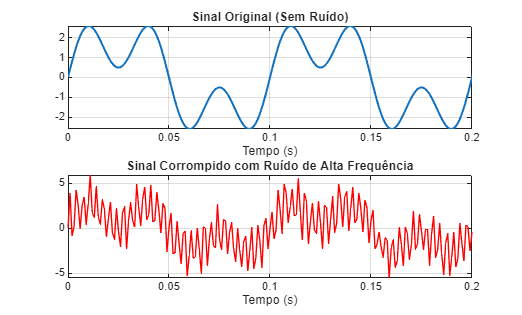

%% Trabalho Computacional -> Sinais e Sistemas (SEL0383):
% Prof. Marcos Rogério Fernandes.
% Título: Filtragem Digital de Sinais: Remoção de Ruído via Filtro
% Passa-Baixa.
% Alunos: 
% João Vitor Miranda Sousa - 14802702
% Fernando Shoji Ogusuku - 15636682


close all; clear all; clc;

%% Passo 1: Gerar Sinal de Teste e Adição de Sinal de Ruído:
% Antes de toda a beleza da coisa, iremos simular um sinal de interesse em baixa frequência e adicionar um
% ruído indesejado em (alta frequência), para simular uma interferência.

fs = 1000;              % Frequência de amostragem (1000 Hz)
t = 0:1/fs:2;           % Vetor de tempo (2 segundos)

% Sinal Desejado: Soma de duas senoides (10 Hz e 30 Hz):
sinal_limpo = 2*sin(2*pi*10*t) + 1.5*sin(2*pi*30*t);

% Sinal de Ruído: Sinal de alta frequência (300 Hz):
ruido = 2.5*sin(2*pi*300*t) + randn(size(t))*0.5;

% Sinal Sujo (Sinal + Ruído):
sinal_sujo = sinal_limpo + ruido;

% Aqui estamos plotando os Sinais no Tempo:
figure;
subplot(2,1,1);
plot(t, sinal_limpo, 'LineWidth', 1.5);
title('Sinal Original (Sem Ruído)'); xlabel('Tempo (s)'); grid on; xlim([0 0.2]);

subplot(2,1,2);
plot(t, sinal_sujo, 'r');
title('Sinal Corrompido com Ruído de Alta Frequência'); xlabel('Tempo (s)'); grid on; xlim([0 0.2]);

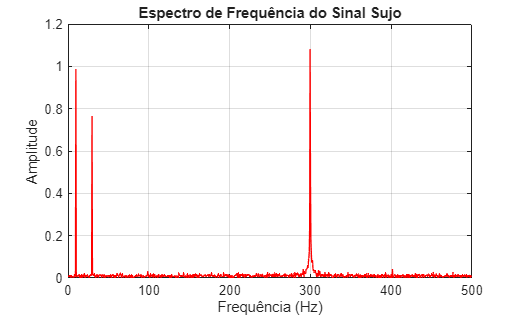


%% Passo 2: Análise de Espectro -> (Transformada de Fourier - FFT):
% Antes de filtrar, precisamos ver onde estão as frequências no espectro
% para projetar o filtro corretamente, utilizaremos a FFT para isso: 

N = length(t);
f = (-N/2:N/2-1)*(fs/N); % Vetor de frequências

% FFT do sinal sujo:
Y_sujo = fftshift(fft(sinal_sujo));
Y_abs = abs(Y_sujo)/N;

figure;
plot(f, Y_abs, 'r', 'LineWidth', 1);
title('Espectro de Frequência do Sinal Sujo');
xlabel('Frequência (Hz)'); ylabel('Amplitude');
grid on; xlim([0 500]);

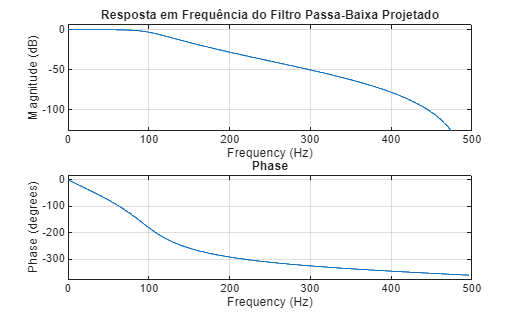

% Observações:
% O gráfico revela picos em 10Hz e 30Hz (referentes ao sinal de interesse)
% e um pico de grande amplitude em 300Hz (referente ao ruído).
% Essa visualização confirma que o ruído está em uma faixa de frequência
% muito superior à do sinal, permitindo sua remoção via filtragem.

%% Passo 3: Projeto e Aplicação do Filtro (Butterworth):
% Como vimos que o sinal útil está abaixo de 50Hz e o ruído está em 300Hz,
% vamos projetar um filtro Passa-Baixa (Low-Pass) com corte em 100Hz:

fc = 100; % Frequência de corte (100 Hz)
ordem = 4; % Ordem do filtro (quanto maior, mais "abrupto" o corte)

% Criação do filtro Butterworth digital:
[b, a] = butter(ordem, fc/(fs/2), 'low');

% Visualização da Resposta em Frequência do Filtro (Diagrama de Bode):
figure;
freqz(b, a, [], fs);
title('Resposta em Frequência do Filtro Passa-Baixa Projetado');

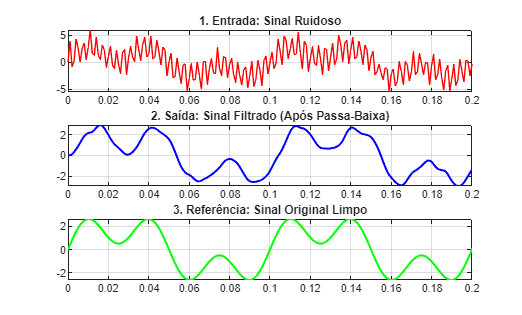


% Aplicação do filtro ao sinal sujo:
sinal_recuperado = filter(b, a, sinal_sujo);

%% Passo 4: Resultados Finais: Comparação:
% Vamos comparar o sinal filtrado com o sinal original limpo:

figure;
subplot(3,1,1);
plot(t, sinal_sujo, 'r'); 
title('1. Entrada: Sinal Ruidoso'); grid on; xlim([0 0.2]);

subplot(3,1,2);
plot(t, sinal_recuperado, 'b', 'LineWidth', 1.5); 
title('2. Saída: Sinal Filtrado (Após Passa-Baixa)'); grid on; xlim([0 0.2]);

subplot(3,1,3);
plot(t, sinal_limpo, 'g', 'LineWidth', 1.5); 
title('3. Referência: Sinal Original Limpo'); grid on; xlim([0 0.2]);


disp('Processo concluído. O ruído de 300Hz foi atenuado com sucesso.');

Processo concluído. O ruído de 300Hz foi atenuado com sucesso.
